# Signal and Image Processing, Module 1 - Project

#### Giovanni Michele Miranda, *507567*

#### Maria Caterina Mottini, *502322*

As first step, we address the images in the created dataset, which is structured as follows:

- Correctly Exposed images

- Overexposed images

- Underexposed images

A common preliminary step is to convert images in **grayscale** and in **double precision **format, in order to simplify data representation and enhances computational efficiency.

% Set the path to the dataset directory
directory = '/Users/giovannimiranda/Downloads/Signal and Image Processing/module 1/project/dataset'

directory = '/Users/giovannimiranda/Downloads/Signal and Image Processing/module 1/project/dataset'

% Recursively search for all .jpeg files in the directory and its subdirectories
files = dir(fullfile(directory, '**', '*.jpeg'));
filenames = {files.name}';
filepaths = cellfun(@(s) fullfile(directory, s), filenames, 'UniformOutput', false);

% Display the number of files found
disp(numel(filenames));

   101



disp(['Number of files found: ', num2str(numel(files))]);

Number of files found: 101


% Process each file
for k = 1:numel(files)
    % Get the full path of the current file
    file_path = fullfile(files(k).folder, files(k).name);
    
    % Read the image
    img = imread(file_path);
    
    % Check if the image is already grayscale
    if ismatrix(img)
        % If already grayscale, skip further processing
        continue;
    else
        % Convert the image to grayscale and double
        img_gray = rgb2gray(img);
        img_gray_resize = imresize(img_gray,[480,640]);
        % Save the processed image back to its original location
        imwrite(img_gray_resize, file_path);
    end
end
disp('All images have been processed and saved.');

All images have been processed and saved.


% Feature extraction function: mean, variance, skewness, entropy, and percentiles
function features = fe_low_level(img)
    
    % Convert images to double
    img = double(img);

    % Compute mean intensity
    mean_val = mean(img(:));
    
    % Compute variance
    variance_val = var(img(:));
    
    % Compute histogram
    [counts, bin_centers] = hist(img(:), 256);    % Normalize histogram

    counts_normalized = counts / sum(counts); % Normalize histogram counts
    counts_nonzero = counts_normalized(counts_normalized > 0); % Remove zero entries
    
    % Compute histogram statistics
    max_val = max(counts_normalized);
    min_val = min(counts_normalized);
    entropy_val = -sum(counts_nonzero .* log2(counts_nonzero)); % Compute entropy
    percentiles = prctile(img(:), [1, 50, 99]);
    
    skeweness_val = skewness(counts_normalized);

    features = [mean_val, variance_val, max_val, min_val, entropy_val, percentiles, skeweness_val];
    
end

% Define the feature extraction function
feature_extractor = @fe_low_level;

% Define directories
classes = {'correctlyexposed', 'overexposed', 'underexposed'};

% Initialize arrays to store features and labels
features = [];
labels = [];

% Loop through each class directory
for label = 1:numel(classes)
    % Get the full path of the current class directory
    current_dir = fullfile(directory, classes{label});
    
    % List all JPEG files in the directory
    files = dir(fullfile(current_dir, '*.jpeg'));
    
    % Extract filenames from the 'files' structure
    filenames = {files.name}';
    
    % Create full file paths for each image file
    filepaths = cellfun(@(s) fullfile(current_dir, s), filenames, 'UniformOutput', false);
    
    fprintf('Processing class: %s, Number of images: %d\n', classes{label}, numel(filepaths));
    
    % Loop through each image file path
    for f = 1:numel(filepaths)
        % Read the image and convert to double precision
        im = im2double(imread(filepaths{f}));
        
        % Extract features using the feature_extractor function handle
        extracted_features = feature_extractor(im);
        
        % Append extracted features to the features array
        features = [features; extracted_features];
        
        % Append the corresponding label (1, 2, or 3)
        labels = [labels; label];
    end
end

Processing class: correctlyexposed, Number of images: 37
Processing class: overexposed, Number of images: 33
Processing class: underexposed, Number of images: 31


disp(features);  disp(labels);

    0.4539    0.0812    0.0137    0.0000    7.4459    0.0235    0.3137    0.9098    1.2809
    0.4976    0.0324    0.0123    0.0000    7.4570    0.0510    0.5137    0.8471    0.5436
    0.4603    0.0629    0.0068    0.0008    7.9079    0.0157    0.4510    0.9843   -0.7698
    0.3701    0.0238    0.0212         0    6.7436    0.1412    0.3333    0.9490    1.5775
    0.5874    0.0368    0.0149    0.0000    7.4592    0.1490    0.6314    0.9255    1.2661
    0.4800    0.0442    0.0214    0.0002    7.4304    0.0039    0.5647    0.9137    2.1987
    0.5105    0.0592    0.0202    0.0002    7.4269         0    0.6275    0.9059    2.2359
    0.4373    0.0399    0.0107    0.0001    7.6577    0.0275    0.4431    0.8706    0.3000
    0.5046    0.0220    0.0124         0    7.2475    0.1843    0.4902    0.8471    0.8393
    0.4549    0.0281    0.0127    0.0000    7.4315    0.0745    0.4549    0.8510    0.8283
    0.5712    0.0227    0.0161         0    7.1564    0.1765    0.6000    0.8157    1.0823

### **CLASSIFICATION**

K-fold cross validation partition
   NumObservations: 101
       NumTestSets: 5
         TrainSize: 81  80  81  81  81
          TestSize: 20  21  20  20  20
          IsCustom: 0


Overall Accuracy (SVM): 89.11%


Overall Accuracy (Decision Tree): 94.06%


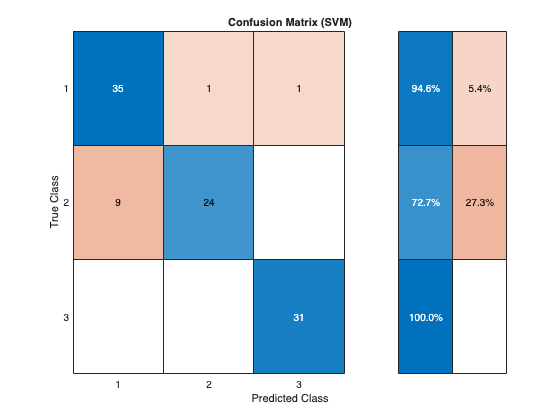

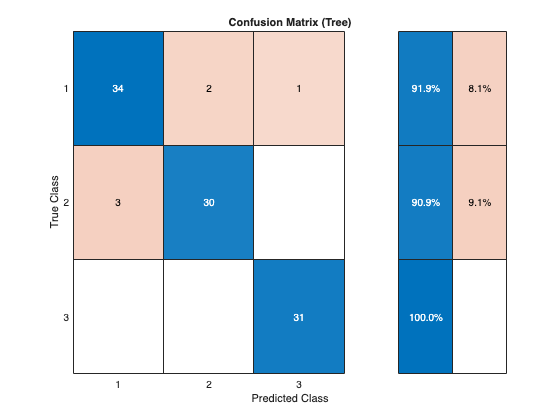

% Define the number of folds for cross-validation
numFolds = 5;

% Create a cross-validation partition object
% It randomly divides the observations into k disjoint folds, each with ~
% same number of observations.
cv = cvpartition(labels, 'KFold', numFolds);

% Initialize accumulators for overall predictions and ground truth
general_y_pred_svm = [];
general_y_test_svm = [];

general_y_pred_tree = [];
general_y_test_tree = [];

% Perform cross-validation for each fold
for i = 1:numFolds
    % Get the training and test indices for the current fold
    idxTrain = training(cv, i);
    idxTest = test(cv, i);
    
    % Split the data into training and test sets
    X_train = features(idxTrain, :); % creates the training feature matrix for i-th fold
    y_train = labels(idxTrain);
    X_test = features(idxTest, :);
    y_test = labels(idxTest);
    

    % Train SVM model
    SVMModel = fitcecoc(X_train, y_train);
    y_pred_svm = predict(SVMModel, X_test);
    % Accumulate predictions and ground truth labels for SVM
    general_y_pred_svm = [general_y_pred_svm; y_pred_svm]; % Append y_pred_svm to the all_y_pred_svm array
    general_y_test_svm = [general_y_test_svm; y_test];
    

    % Train decision tree model
    TreeModel = fitctree(X_train, y_train);
    y_pred_tree = predict(TreeModel, X_test);
    % Accumulate predictions and ground truth labels for Decision Tree
    general_y_pred_tree = [general_y_pred_tree; y_pred_tree];
    general_y_test_tree = [general_y_test_tree; y_test];
end

% Calculate overall accuracies
accuracy_svm = sum(general_y_pred_svm == general_y_test_svm) / numel(general_y_test_svm);
accuracy_tree = sum(general_y_pred_tree == general_y_test_tree) / numel(general_y_test_tree);
disp(cv)

**Key Points:**

- **Same Training and Testing Sets**: Each model (SVM, Decision Tree) uses the same training and testing sets for each fold, ensuring a fair comparison.

- **Accumulate Predictions and Labels**: Predictions and true labels are accumulated across all folds to compute overall accuracy and confusion matrices.

- **Cross-Validation**: The data is divided into `K` folds, and each model is trained and tested `K` times, each time using a different fold as the test set and the remaining `K-1` folds as the training set

**Support Vector Machine (SVM) - **`fitcecoc`:

- **Function**: `fitcecoc` stands for "fit error-correcting output codes".

- **Purpose**: This function is used to train multiclass models using a combination of binary SVM models. SVMs are inherently binary classifiers, so for multiclass classification problems, an approach like Error-Correcting Output Codes (ECOC) is used to combine multiple binary SVMs.

- **Why **`fitcecoc`: It is specifically designed to handle multiclass problems with SVMs and provides a convenient way to train an ensemble of binary SVM classifiers.

**Decision Tree - **`fitctree`:

- **Function**: `fitctree` stands for "fit classification tree".

- **Purpose**: This function trains a decision tree classifier, which is a tree-structured model used to make predictions based on the features of the input data. The tree is built by recursively splitting the data based on feature values to maximize some criterion like information gain or Gini impurity.

- **Why **`fitctree`: It is specifically designed to construct decision trees for classification tasks, providing various options for tree depth, splitting criteria, and pruning.

**Summary:**

- `fitcecoc`** for SVM**: Combines multiple binary SVM classifiers for multiclass problems using the ECOC framework.

- `fitctree`** for Decision Tree**: Builds a decision tree classifier, handling the recursive partitioning of data

% Display mean accuracies
fprintf('Overall Accuracy (SVM): %.2f%%\n', accuracy_svm  * 100);
fprintf('Overall Accuracy (Decision Tree): %.2f%%\n', accuracy_tree * 100);
% Compute overall confusion matrices
conf_matrix_svm = confusionchart(general_y_test_svm, general_y_pred_svm); conf_matrix_svm.RowSummary = 'row-normalized'; conf_matrix_svm.Title = 'Confusion Matrix (SVM)';
conf_matrix_tree = confusionchart(general_y_test_tree, general_y_pred_tree); conf_matrix_tree.RowSummary = 'row-normalized'; conf_matrix_tree.Title = 'Confusion Matrix (Tree)';

% Save the trained TREE model (since the best in terms of performance)
save('trainedClassifierTree.mat', 'TreeModel');
save('cv_partition_tree.mat', 'cv', 'general_y_pred_tree', 'general_y_test_tree');
save('predictionsTree.mat', 'general_y_pred_tree');

% Store mean values for images features -- We can have an idea of our dataset statistics
features_all = struct();

for label = 1:numel(classes)
    current_dir = fullfile(directory, classes{label});
    
    % List all JPEG files in the directory
    files = dir(fullfile(current_dir, '*.jpeg'));
    
    % Initialize a matrix to store features for the current class
    features_class = [];
    
    % Process each image in the class directory
    for f = 1:numel(files)
        file_path = fullfile(files(f).folder, files(f).name);
        
        % Read the image
        img = im2double(imread(file_path));
        
        % Convert to grayscale if necessary
        if ~ismatrix(img)
            img_gray = rgb2gray(img);
        else
            img_gray = img;  % Already grayscale
        end
        
        % Resize the grayscale image
        img_gray_resize = imresize(img_gray, [480,640]);
        
        % Extract features from the resized grayscale image
        features_temp = fe_low_level(img_gray_resize);
        
        % Append features to the class features matrix
        features_class = [features_class; features_temp];
    end
    
    % Store features for the current class in the features_all struct
    features_all.(classes{label}) = features_class;
    
    % Compute and print mean values of features for the current class
    mean_features = mean(features_class, 1);

-Class: correctlyexposed


Mean Intensity: 0.48


Variance: 0.04


Entropy: 7.43 

Skewness: 1.12


-Class: overexposed


Mean Intensity: 0.69


Variance: 0.07


Entropy: 7.04 

Skewness: 6.99


-Class: underexposed


Mean Intensity: 0.21


Variance: 0.03


Entropy: 6.53 

Skewness: 2.89


    fprintf('-Class: %s\n', classes{label});
    fprintf('Mean Intensity: %.2f\n', mean_features(1));
    fprintf('Variance: %.2f\n', mean_features(2));
    fprintf('Entropy: %.2f %.2f %.2f\n', mean_features(5));
    fprintf('Skewness: %.2f\n', mean_features(9));
    fprintf('\n');
end

### **Gamma Correction **

%%% AUTO-CORRECTIVE METHOD

output_dir = '/Users/giovannimiranda/Downloads/Signal and Image Processing/module 1/project/dataset_corrected';

% Recursively search for all .jpg files in the dataset directory
files = dir(fullfile(directory, '**', '*.jpeg'));
filepaths = fullfile({files.folder}, {files.name});
filepaths = reshape(filepaths, [], 1);

% Initialize variables
count_corrected = 0;
max_iterations = 35;
gamma_applied = [];
new_pred_group = [];
predictions = general_y_pred_tree;
base_gamma = 1;

% Loop through each image file
for i = 1:numel(filepaths)
    iterations = 0;
    change_step = 0.25;
    change = change_step;

    img_path = filepaths{i};
    img = imread(img_path);

    % Assume predictions contains the initial labels for the images
    initial_pred = predictions(i); % Store the initial label
    if initial_pred == 1
        new_pred_group = [new_pred_group; initial_pred];
        continue;
    end

    if initial_pred ~= 1
    while initial_pred ~= 1 && (iterations < max_iterations)
        if predictions(i) == 3
            % Underexposed: increase brightness
            gamma = abs(base_gamma - change);
        elseif predictions(i) == 2
            %gamma = base_gamma + change; % Overexposed: decrease brightness
            gamma = base_gamma + change;
        end

        % Convert the image to grayscale
        img_gray = im2gray(img);
        img_gray = imresize(img_gray, [480,640]);
        double_image = im2double(img_gray);

        % Apply gamma correction
        img_gamma = double_image .^ gamma;
        corrected_image = img_gamma;

        % Extract features from the gamma-corrected image
        features_corr = fe_low_level(corrected_image);

        % Get a new prediction
        new_pred = predict(TreeModel, features_corr);

        if new_pred == 1
            count_corrected = count_corrected + 1;
            initial_pred = 1;
            gamma_applied = [gamma_applied; i, gamma];
            
            % Save the corrected image
            [~, filename, ext] = fileparts(img_path);
            gamma_file_path = fullfile(output_dir, [filename, '_corrected', ext]);
            imwrite(corrected_image, gamma_file_path);
        else
            if (predictions(i) == 2 && new_pred == 3)
                change_step = change_step * 0.8;
                change = change - change_step;
            elseif (predictions(i) == 3 && new_pred == 2)
                change_step = change_step * 0.8;
                change = change - change_step;
            else
                change = change + 0.1; 
            end
        end

        initial_pred = new_pred;
        iterations = iterations + 1;
    end
    if initial_pred ~= 1
        [~, filename, ext] = fileparts(img_path);
        gamma_notcorr_filepath = fullfile(output_dir, [filename, '_NOTcorrect', ext]);
        imwrite(img, gamma_notcorr_filepath);
    end    
    new_pred_group = [new_pred_group; initial_pred];
    end
end


% %%% VERY BRUTE-FORCE METHOD (not coherent indeed with the project indications)

% output_dir = '/Users/giovannimiranda/Downloads/Signal and Image Processing/module 1/project/dataset_corrected';
% 
% % Recursively search for all .jpg files in the dataset directory
% files = dir(fullfile(directory, '**', '*.jpeg'));
% filepaths = fullfile({files.folder}, {files.name});
% filepaths = reshape(filepaths, [], 1);
% 
% % Initialize variables
% count_corrected = 0;
% base_gamma = 1;
% max_iterations = 35; % Max iterations to prevent infinite loop
% gamma_matrix = [];
% new_pred_list = [];
% predictions = general_y_pred_tree;
% 
% % Define a range of gamma values to experiment with
% gamma_values = [0.1, 0.2, 0.5, 0.7, 0.9, 1.1, 1.3, 1.5, 1.8, 2.0, 2.3, 2.5, 3];
% 
% % Loop through each image file
% for i = 1:numel(filepaths)
%     img_path = filepaths{i};
%     img = imread(img_path);
% 
%     % Assume predictions contains the initial labels for the images
%     initial_pred = predictions(i); % Store the initial label
%     if initial_pred == 1
%         new_pred_list = [new_pred_list; initial_pred];
%         continue;
%     end
% 
%     corrected = false;
%     for gamma = gamma_values
%         if corrected
%             break;
%         end
% 
%         % Convert the image to grayscale
%         img_gray = im2gray(img);
%         img_gray = imresize(img_gray, [640, 480]);
%         double_image = im2double(img_gray); % Convert grayscale image to double
% 
%         % Apply gamma correction
%         img_gamma = double_image .^ gamma;
%         corrected_image = img_gamma;
% 
%         % Extract features from the gamma-corrected image
%         features_corr = fe_low_level(corrected_image);
% 
%         % Predict the new label
%         new_pred = predict(TreeModel, features_corr);
% 
%         if new_pred == 1
%             count_corrected = count_corrected + 1;
%             initial_pred = 1;
%             gamma_matrix = [gamma_matrix; i, gamma];
%             % Save the corrected image
%             [~, filename, ext] = fileparts(img_path);
%             gamma_file_path = fullfile(output_dir, [filename, '_corrected', ext]);
%             imwrite(corrected_image, gamma_file_path);
%             corrected = true;
%         end
%     end
% 
%     if initial_pred ~= 1
%         % Save the original image if it couldn't be corrected

new_pred_group =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


count = 0

%         [~, filename, ext] = fileparts(img_path);
%         original_file_path = fullfile(directory, [filename, '_NOTcorrect', ext]);
%         imwrite(img, original_file_path);

ans =     8.0000    1.2500
    9.0000    1.2500
   10.0000    1.2500
   11.0000    1.2500
   12.0000    0.8900
   14.0000    1.2500
   15.0000    0.7500
   16.0000    0.7500
   17.0000    0.7500
   18.0000    0.7500


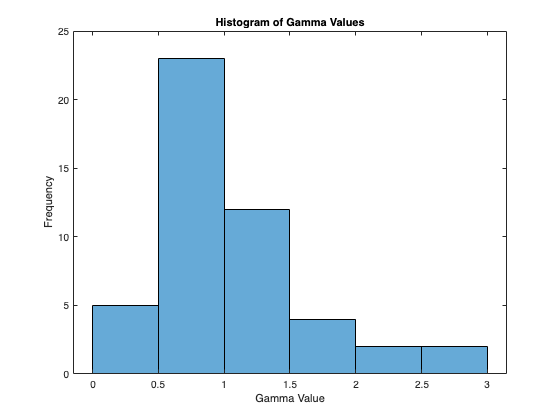

%     end    
%     new_pred_list = [new_pred_list; initial_pred];
% end   

The value of gamma applied to the single images are entirely stores in the *gamma_applied *matrix. Below we can appreciate some statistics which offer deeper insights about the applied corrections.

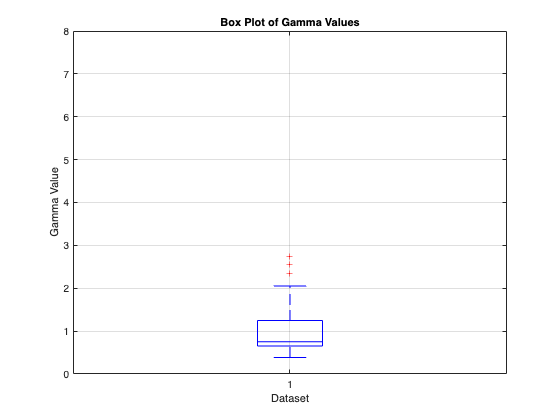

gamma_applied(1:10, :)
figure;
histogram(gamma_applied(:,2));
title('Histogram of Gamma Values');
xlabel('Gamma Value');
ylabel('Frequency');
% Extract gamma values
gamma_values = gamma_applied(:, 2);

% Create box plot

figure;
boxplot(gamma_values, 'Colors', 'b', 'Whisker', 1.5);
title('Box Plot of Gamma Values');
xlabel('Dataset');
ylabel('Gamma Value'); ylim([0,8])
grid on;

% Load the trained classifier
classifier_path = 'trainedClassifierTree.mat';
load(classifier_path, 'TreeModel')

The cells below are used to classify the corrected images, to hopefully obtain "**correctly exposed**" classification!

% Classify the predictions
corrected_image_path = '/Users/giovannimiranda/Downloads/Signal and Image Processing/module 1/project/dataset_corrected';
predictions = {};

% List all JPEG files in the directory
files_n = dir(fullfile(corrected_image_path, '*.jpeg'));

% Extract filenames from the 'files' structure
filenames_n = {files_n.name}';

% Create full file paths for each image file
filepaths_n = cellfun(@(s) fullfile(corrected_image_path, s), filenames_n, 'UniformOutput', false);

%fprintf('Processing class: %s, Number of images: %d\n', corrected_image_path, numel(filepaths_n));
%Loop through each image file path
for f = 1:numel(filepaths_n)
    % Read the image
    corrected_image = imread(filepaths_n{f});
    corrected_image = im2double(corrected_image);
    % Extract features from the external image using our feature extraction function
    features_image = fe_low_level(corrected_image);

    % Predicting through our trained classifier
    predicted_class_idx = predict(TreeModel, features_image);
    predicted_class = classes{predicted_class_idx};
    predictions = [predictions; {filepaths_n{f}, predicted_class}];
end
% %Print the predictions
% for i = 1:size(predictions, 1)
%     fprintf('Predicted Class: %s\n', predictions{i, 2});
% end
count_overexps = 0;
count_correctly = 0;
count_underexps = 0;

% Iterate through predictions and count occurrences
for i = 1:size(predictions, 1)
    predicted_class = predictions{i, 2}; % Get predicted class from second column
    
    % Count occurrences based on predicted class
    if strcmp(predicted_class, 'correctlyexposed')
        count_correctly = count_correctly + 1;
    elseif strcmp(predicted_class, 'overexposed')
        count_overexps = count_overexps + 1;
    elseif strcmp(predicted_class, 'underexposed')

Number of correctly exposed images: 45
Number of overexposed images: 11
Number of underexposed images: 8

Number of initially overexposed and underexposed images: 66

Percentage of correctly exposed images: 68.18%

        count_underexps = count_underexps + 1;
    end
end
% Display counts
fprintf('Number of correctly exposed images: %d\n', count_correctly); fprintf('Number of overexposed images: %d\n', count_overexps); fprintf('Number of underexposed images: %d\n', count_underexps); fprintf('\nNumber of initially overexposed and underexposed images: %d\n', 66); fprintf('\nPercentage of correctly exposed images: %.2f%%', (count_correctly/(103-37))*100);

### **RESULTS EVALUATION**

In order to deeply evaluate the results of the gamma correction applied, we can think about several analysis about the **histogram** of the corrected images.    

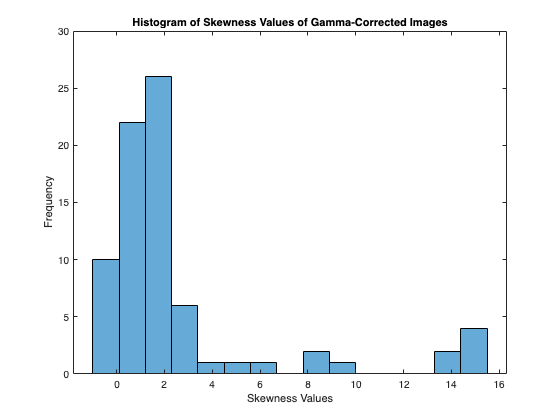

% Loop through each image file path
corrected_final_features = [];
for f = 1:numel(filepaths_n)
    % Read the image and convert to double precision
    im = im2double(imread(filepaths_n{f}));
        
    % Extract features using the feature_extractor function handle
    correct_extracted_features = feature_extractor(im);
        
    % Append extracted features to the features array
    corrected_final_features = [corrected_final_features; correct_extracted_features];
end
skewness_corrimages = corrected_final_features(:,9);
% Create a histogram of skewness values
figure;

histogram(skewness_corrimages, 15); % You can adjust the number of bins as needed
xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images');
% Load the skewness values
skewness_corrimages = corrected_final_features(:, 9);

% Calculate the 15th and 85th percentiles for the 80% confidence interval

The 80% confidence interval for skewness values is [0.04, 8.42]


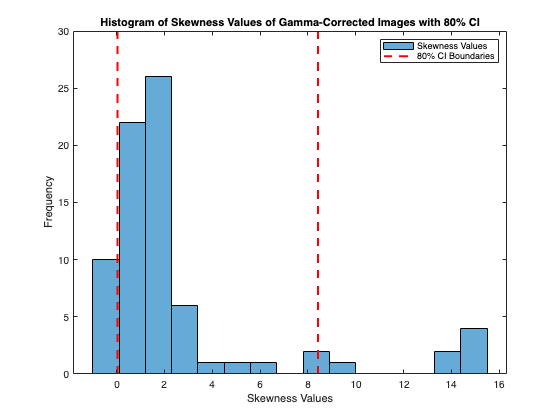

lower_bound = prctile(skewness_corrimages, 10);
upper_bound = prctile(skewness_corrimages, 90);

fprintf('The 80%% confidence interval for skewness values is [%.2f, %.2f]\n', lower_bound, upper_bound);
figure;
histogram(skewness_corrimages, 15);
hold on;
% Add lines for the 80% confidence interval
y_limits = ylim;
plot([lower_bound, lower_bound], y_limits, 'r--', 'LineWidth', 2);
plot([upper_bound, upper_bound], y_limits, 'r--', 'LineWidth', 2);
hold off;

xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images with 80% CI');
legend('Skewness Values', '80% CI Boundaries');
% Calculate the mean and median of skewness values

The mean skewness value is 2.68


mean_skewness = mean(skewness_corrimages);

The median skewness value is 1.50


median_skewness = median(skewness_corrimages);

fprintf('The mean skewness value is %.2f\n', mean_skewness);

Unrecognized function or variable 'skewness_values'.

fprintf('The median skewness value is %.2f\n', median_skewness);
% Create a histogram of skewness values
figure;
histogram(skewness_values, 15);
hold on;
% Add lines for the mean and median
y_limits = ylim;
plot([mean_skewness, mean_skewness], y_limits, 'g--', 'LineWidth', 2);
plot([median_skewness, median_skewness], y_limits, 'b--', 'LineWidth', 2);
hold off;
xlabel('Skewness Values');
ylabel('Frequency');
title('Histogram of Skewness Values of Gamma-Corrected Images with Mean and Median');
legend('Skewness Values', 'Mean', 'Median');